# Compare Practical and Perfect Channel Estimates

Generate physical broadcast channel (PBCH) demodulation reference signal (DM-RS) symbols for physical layer cell identity number 42. The time-dependent part of the DM-RS scrambling initialization is 0.

ncellid = 42;
ibar_SSB = 0;
dmrsSym = nrPBCHDMRS(ncellid,ibar_SSB);

Obtain resource element indices for the PBCH DM-RS.

dmrsInd = nrPBCHDMRSIndices(ncellid);

Create a resource grid containing the generated DM-RS symbols.

nrb = 20;
scs = 15;
carrier = nrCarrierConfig('NSizeGrid',nrb,'SubcarrierSpacing',scs);
nTxAnts = 2;
nRxAnts = 2;
txGrid = nrResourceGrid(carrier,nTxAnts);
txGrid(dmrsInd) = dmrsSym;

Modulate the resource grid using the specified FFT length and cyclic prefix length.   

ofdmInfo = nrOFDMInfo(carrier);
txWaveform = nrOFDMModulate(carrier,txGrid);

Create a TDL-C channel model with the specified properties. 

channel = nrTDLChannel;
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;
channel.SampleRate = ofdmInfo.SampleRate;
channel.DelayProfile = 'TDL-C';
channel.DelaySpread = 100e-9;
channel.MaximumDopplerShift = 20;

Get the maximum channel delay.

chInfo = info(channel);
maxChDelay = chInfo.MaximumChannelDelay;

To flush delayed samples from the channel, append zeros at the end of the transmitted waveform corresponding to the maximum number of delayed samples and the number of transmit antennas. Transmit the padded waveform through the TDL-C channel model. 

[rxWaveform,pathGains] = channel([txWaveform; zeros(maxChDelay,nTxAnts)]);

Estimate timing offset for the transmission using the DM-RS symbols as reference symbols. The OFDM modulation of the reference symbols uses an initial slot number of 0. 

initialSlot = 0;
offset = nrTimingEstimate(carrier,rxWaveform,txGrid);

Synchronize the received waveform according to the estimated timing offset. 

rxWaveform = rxWaveform(1+offset:end,:);

 Create a received resource grid containing the demodulated and synchronized received waveform.

cpFraction = 0.55;
rxGrid = nrOFDMDemodulate(carrier,rxWaveform,'CyclicPrefixFraction',cpFraction);

 Obtain the practical channel estimate.

H = nrChannelEstimate(rxGrid,dmrsInd,dmrsSym);

Obtain the perfect channel estimate.

pathFilters = getPathFilters(channel);
H_ideal = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset);

 Compare practical and perfect channel estimates. 

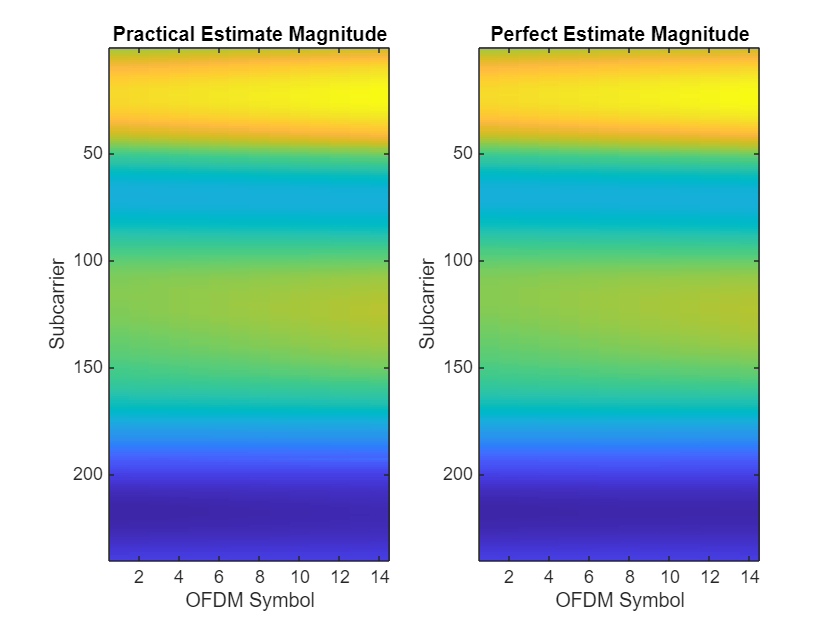

figure;
subplot(1,2,1);
imagesc(abs(H(:,:,1)));
xlabel('OFDM Symbol');
ylabel('Subcarrier');
title('Practical Estimate Magnitude');
subplot(1,2,2);
imagesc(abs(H_ideal(:,:,1)));
xlabel('OFDM Symbol');
ylabel('Subcarrier');
title('Perfect Estimate Magnitude');

*Copyright 2019-2023 The MathWorks, Inc.*